fnHead = 'D:\SPMDATAActive\Z-Spectroscopy_newBuilding000'

fnHead = 'D:\SPMDATAActive\Z-Spectroscopy_newBuilding000'

fnNum = ['01'; '02'; '03'; '04'; '05'; '06'; '07'; '08'; '09'; '10']

fnNum = 10×2 char 배열
    '01'
    '02'
    '03'
    '04'
    '05'
    '06'
    '07'
    '08'
    '09'
    '10'


fnTail= '.dat'

fnTail = '.dat'

fns = [repmat(fnHead,10,1) fnNum repmat(fnTail,10,1)]

fns = 10×52 char 배열
    'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00001.dat'
    'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00002.dat'
    'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00003.dat'
    'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00004.dat'
    'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00005.dat'
    'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00006.dat'
    'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00007.dat'
    'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00008.dat'
    'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00009.dat'
    'D:\SPMDATAActive\Z-Spectroscopy_newBuilding00010.dat'


wfs= nan(1,10)

wfs =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


for ind = 1:10
    wf = getWF(fns(ind,:),0.14);
    wfs(ind) = wf;
end
wfs

wfs =     3.8085    3.2137    4.0259    3.0717    1.1432    3.9355    3.5528    1.7475    2.9958    3.6896


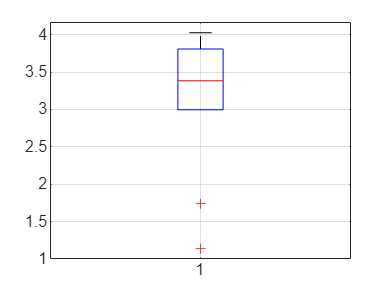

boxplot(wfs)
grid on

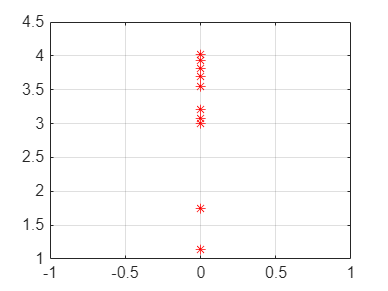

plot(zeros(1,10),wfs,'r*')
grid on

function wf = getWF(fn,elb)
%determine Elbow
[header, data, channels] = loaddat(fn);
x = data(:,1);
y = abs(data(:,2));
xcut = quantile(x,elb);
[~,argXcut] = min(abs((x-xcut)));

%Linear fitting
xEff = x(1:argXcut);
lyEff = log(y(1:argXcut));
result = fitlm(xEff,lyEff);
pred = result.predict(xEff);

%determine WF
me = 9.1093837*10^(-31); % Electron Mass (kg)
hbar = 1.054571817*10^(-34); % Planck Constant (J/s)
a = result.Coefficients.Estimate(2);
qe = 1.60217663 * 10^(-19);
phiV = ((a*hbar)^2)/(8*me);
wf = phiV/qe;
end

function [header, data, channels] = loaddat(fn)
% loaddat  Nanonis DAT ASCII file loader
%   [header, data, channels] = loaddat(fn) reads a Nanonis 
%   DAT ASCII file fn.
%   fn: path of the .dat file to read.
%   header: header info of the data file.
%   data: contains the data of all channels, each column in the
%       data array corresponds to an acquired channel.
%   channels: contains the names of the data channels.

data=''; header=''; channels='';

if exist(fn, 'file')
    fid = fopen(fn, 'r', 'ieee-be');    % open with big-endian
else
    fprintf('File does not exist.\n');
    return;
end

% read header data
% The header consists of key-value pairs, separated by a tab character
% e.g. Settling time (s)	200E-6	
% The beginning of the data block starts with [DATA]
while 1
    s = strtrim(fgetl(fid));
    if strcmp(upper(s),'[DATA]')
        break
    end
    
    %s1 = strsplit(s,char(9));  % not defined in older Matlab versions
    s1 = strsplit_i(s,char(9));
    s1_s = prod(size(s1));
    if s1_s > 0 % line contains a tab
        s_key = strrep(lower(s1{1}), ' ', '_');
        s_val = '';
        if s1_s > 1
            s_val = strrep(s1{2}, '"', '');
        end
        
        s_key = regexprep(lower(s_key), '[^a-z0-9_]', '_');
        header.(s_key) = s_val;
    end
end

% read the channel names
s = strtrim(fgetl(fid));
%channels = strsplit(s,'=');  % not defined in older Matlab versions
channels = strsplit_i(s,char(9));

% read the data
data = fscanf(fid, '%f', [prod(size(channels)) Inf]);
data = transpose(data);

fclose(fid);
end


function s = strsplit_i(str, delim)
    s = {};
    while ~isempty(str),
        [t,str] = strtok(str, delim);
        s{end+1} = t;
    end
end
